x1 = [0;-5;0];
x2 = [0;10;0];
X0 = [x1;x2];
V0 = zeros(6,1);

rest_length = 10;

h = 1/60;

M = 0.2*eye(6);
M_inv = inv(M);

ks = 10;
ka = 20;

%prefactorisation:
% step 1: form L
% step 2: form J
% step 3: form A = M + h*h*L

% iterate constraints:
% C1: spring constraints:
m_p1 = 1;
m_p2 = 2;
c1 = 1;
% step 1: set L
L_triplets_c1 = [
    3 * m_p1 - 2, 3 * m_p1 - 2, ks;
    3 * m_p1 - 1, 3 * m_p1 - 1, ks;
    3 * m_p1 - 0, 3 * m_p1 - 0, ks;

    3 * m_p1 - 2, 3 * m_p2 - 2, -ks;
    3 * m_p1 - 1, 3 * m_p2 - 1, -ks;
    3 * m_p1 - 0, 3 * m_p2 - 0, -ks;

    3 * m_p2 - 2, 3 * m_p1 - 2, -ks;
    3 * m_p2 - 1, 3 * m_p1 - 1, -ks;
    3 * m_p2 - 0, 3 * m_p1 - 0, -ks;

    3 * m_p2 - 2, 3 * m_p2 - 2, ks;
    3 * m_p2 - 1, 3 * m_p2 - 1, ks;
    3 * m_p2 - 0, 3 * m_p2 - 0, ks;
    ];
% step 2: set J
J_triplets_c1 = [
    3 * m_p1 - 2, 3 * c1 - 2, ks; 
    3 * m_p1 - 1, 3 * c1 - 1, ks; 
    3 * m_p1 - 0, 3 * c1 - 0, ks; 

    3 * m_p2 - 2, 3 * c1 - 2, -ks;
    3 * m_p2 - 1, 3 * c1 - 1, -ks;
    3 * m_p2 - 0, 3 * c1 - 0, -ks;
    ];
% step 3: set D
%di = [x1-x2];
%D_vector_c1 = [di/norm(di)*rest_length];


% C2: attachment constraints:
fixpoint = x2;
m_p0 = 2;
c2 = 2;
% step 1: set L
L_triplets_c2 = [
    3 * m_p0 - 2, 3 * m_p0 - 2, ka;
    3 * m_p0 - 1, 3 * m_p0 - 1, ka;
    3 * m_p0 - 0, 3 * m_p0 - 0, ka;
    ];
%step 2: set J
J_triplets_c2 = [
    3 * m_p0 - 2, 3 * c2 - 2, ka; 
    3 * m_p0 - 1, 3 * c2 - 1, ka; 
    3 * m_p0 - 0, 3 * c2 - 0, ka; 
    ];
%step 3: set D
D_vector_c2 = [fixpoint];

%concatenation:
L_triplets = [L_triplets_c1;L_triplets_c2];
J_triplets = [J_triplets_c1;J_triplets_c2];
%D_vector = [D_vector_c1;D_vector_c2];

L = sparse(L_triplets(:,1),L_triplets(:,2),L_triplets(:,3));
J = sparse(J_triplets(:,1),J_triplets(:,2),J_triplets(:,3));

A = M + h*h*L;
% this is the end of prefactorisation

%Start sim loop:
step = 200;
Point1_position = zeros(1,step);
Point2_position = zeros(1,step); %fixed point
System_Energy   = zeros(1,step);
Point1_velocity = zeros(1,step);
Point2_velocity = zeros(1,step);
Spring_length   = zeros(1,step);

ex_Point1_position = zeros(1,step);
ex_Point2_position = zeros(1,step); %fixed point
ex_System_Energy   = zeros(1,step);
ex_Point1_velocity = zeros(1,step);
ex_Point2_velocity = zeros(1,step);
ex_Spring_length   = zeros(1,step);




for i = 1:step
  % step1: find D_vec
    di = x1-x2;
    D_vector_c1 = [di/norm(di)*rest_length];
    D = [D_vector_c1;D_vector_c2];
  % step2: find inertia Y
    Y = X0+V0*h;
    for j = 1:10
      % step3: solve Ax = b
        b = M*Y + h*h*J*D;
        X1 = A\b;
        Y = X1;
    end
    V1 = (X1 -X0) / h;
  % record printing variables
    Point1_position(i) = X1(2);
    Point2_position(i) = X1(5); %fixed point
    Point1_velocity(i) = V1(2);
    Point2_velocity(i) = V1(5);
    X0 = X1;
    x1 = X0(1:3);
    x2 = X0(4:6);
    l1 = norm(x1-x2);
    Spring_length(i)   = l1;
    vnorm = norm(V1);
    % not consider the attachment constraints energy
    energy = 0.5*0.2*vnorm*vnorm + 0.5*ks*(l1-rest_length)*(l1-rest_length);
    %la = norm(x2 - fixpoint);
    %energy = energy+ 0.5*ka*la;
    System_Energy(i)   = energy;
  % set varible for next frame
    V0 = V1;
end

% explicit method:

F = [0;0;0;0;0;0];
x1 = [0;-5;0];
x2 = [0;10;0];
X0 = [x1;x2];
V0 = zeros(6,1);

for i=1:step
    F(2) = ks*((x2(2)-x1(2)) - rest_length);
    V1 = V0 + h*(M\F);
    X1 = X0 + h*(V0+V1)/2;
    ex_Point1_position(i) = X1(2);
    ex_Point2_position(i) = X1(5); %fixed point
    ex_Point1_velocity(i) = V1(2);
    ex_Point2_velocity(i) = V1(5);
    
    X0 = X1;
    x1 = X0(1:3);
    x2 = X0(4:6);
    l1 = norm(x1-x2);
    ex_Spring_length(i)   = l1;
    vnorm = norm(V1);
    % not consider the attachment constraints energy
    energy = 0.5*0.2*vnorm*vnorm + 0.5*ks*(l1-rest_length)*(l1-rest_length);
    %la = norm(x2 - fixpoint);
    %energy = energy+ 0.5*ka*la;
    ex_System_Energy(i)   = energy;
  % set varible for next frame
    V0 = V1;


end


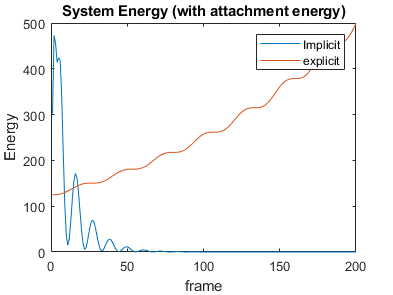

figure
plot(System_Energy)
hold on
plot(ex_System_Energy)
legend('Implicit','explicit')
title('System Energy (with attachment energy)')
xlabel('frame')
ylabel('Energy')

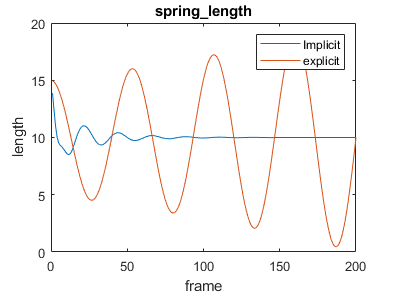


figure
plot(Spring_length)
hold on
plot(ex_Spring_length)
legend('Implicit','explicit')
title('spring\_length')
xlabel('frame')
ylabel('length')

%Converge:
